# Design and Analysis of Grid-Forming Converter 

This design solution shows you how to implement and analyze the performance of a grid-forming (GFM) converter. Modern power systems comprise numerous energy sources with power converter interfaces. These converter units are connected at distribution level and sub-transmission voltage levels. With the rise of power electronics interfaced renewable sources and the gradual reduction in numbers of synchronous machines, contemporary power systems face challenges with low inertia and limited short-circuit current capacity. These challenges cannot be solved with a traditional grid-following converter control strategy based on grid measurements and phase locked loops. In this case, grid-forming converters are a better alternative to the traditional grid-following converters.

The grid-forming converter internally generates voltage and frequency references without grid measurements and behaves like a voltage source behind an impedance. The grid-forming control strategy emulates the inertia to improve the grid strength, enhances the damping, and provides better voltage control. There are many control strategies available for a grid-forming converter. The control strategies in this workflow are droop control and virtual synchronous machine (VSM) control. In VSM control, the converter control strategy mimics the dynamic response of a traditional synchronous machine. This strategy mimics the inertia, damping, and also provides better grid voltage support.

Use Simscape™ Electrical™  to verify whether the grid-forming converter design meets the performance requirements of the recommended grid code standards, including GC0137 [1], FERC Order No's 827 [2], 828 [3], and 842 [4].

## Scope of Design Solution

This design solution designs a grid-forming converter control and provides a test infrastructure that you can use to investigate various grid-forming controller settings and operating scenarios. 

The design solution scope includes:

- Identifying performance requirements from the grid code standard

- Design of grid-forming control using droop and VSM control methods

- Design of different current limitation strategies using virtual impedance and current saturation methods.

- Verification of the grid-forming technical specifications from grid operators for changes in voltage, frequency, and phase.

- System performance evaluation with change in inertia, damping, and fault ride-through methods.

## System Overview

This figure shows a top-level schematic of a grid-forming converter system. The model has a 500 kVA, 415 V, 50 Hz, three-phase grid-forming converter connected to a 415 V/11 kV step-up transformer. A transmission line connects the transformer to the 11 kV grid. A local load is connected to the GFM converter output at the low voltage level. The grid-forming converter model provides the test harness that allows you to change the grid voltage, frequency, phase, local load, short-circuit ratio (SCR), X/R ratio, power reference, islanding mode, and apply faults. 

This workflow includes a generic grid-forming converter controller. The per-unit active and reactive power references, the measured output voltage, in Volts, and the current, in Amperes, are the inputs to the controller. The per-unit measured output active and reactive power and the coverter modulation signal are the outputs of the controller.  

The [`GridFormingConverterInputParameters`](matlab:open('./GridFormingConverterInputParameters.mlx')) MLX file specifies all the grid-forming converter parameters.

Open the model `GridFormingConverter`                                           

 
open_system('GridFormingConverter');

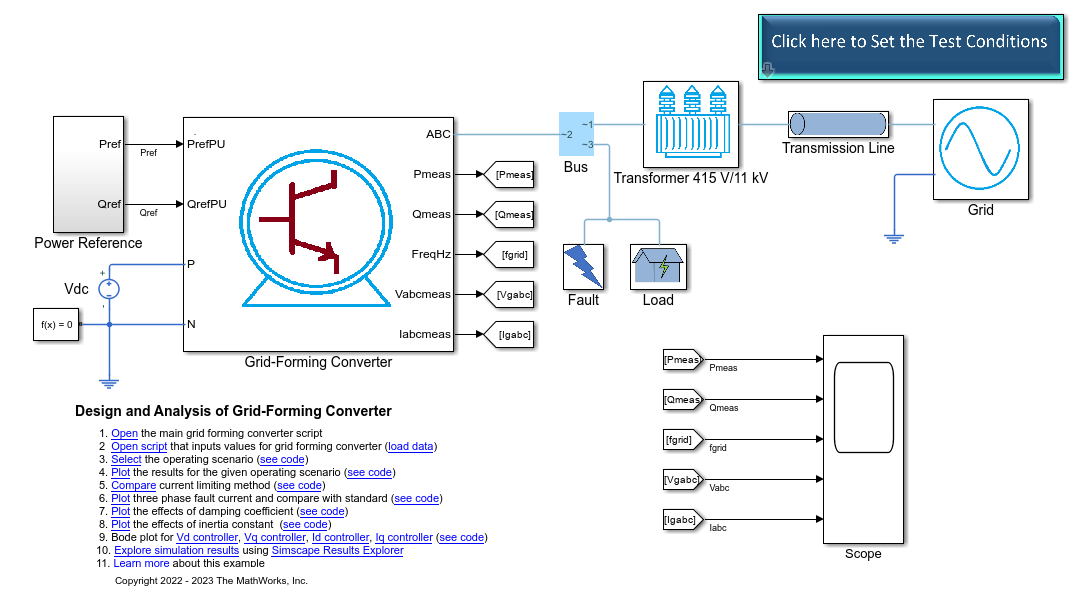

 To open and load input parameters of the grid-forming converter.                                                              

 
edit 'GridFormingConverterInputParameters.mlx';
% Loading the GFM converter input parameters
GridFormingConverterInputParameters;

## Grid-Forming Controller

The grid-forming controller regulates active power, reactive power$\;\left(P_{\textrm{ref}} ,Q_{\textrm{ref}} \right)$, frequency$\left(f_{\textrm{ref}} =1\;\textrm{pu}\right)$, and voltage($V_{\textrm{ref}} =1\;\textrm{pu}$) in a converter system by incorporating active power, reactive power, outer voltage, and inner current controllers. It implements a fault ride-through algorithm to ensure stable operation during grid disturbances. The active and reactive power controllers set the required voltage reference $\left(V_{\textrm{dref}} \;\textrm{and}\;V_{\textrm{qref}} \right)$ to maintain the desired power reference, voltage, and frequency. During faulted conditions, the voltage reference is modified by the fault ride-through method to provide the required reactive power. The outer voltage controller maintains the voltage reference by setting the required current reference $\left(I_{\textrm{dref}} \;\textrm{and}\;I_{\textrm{qref}} \right)$, while the inner current controller generates three-phase modulation signals that are fed to the converter.

  This figure shows the GFM controller block diagram.

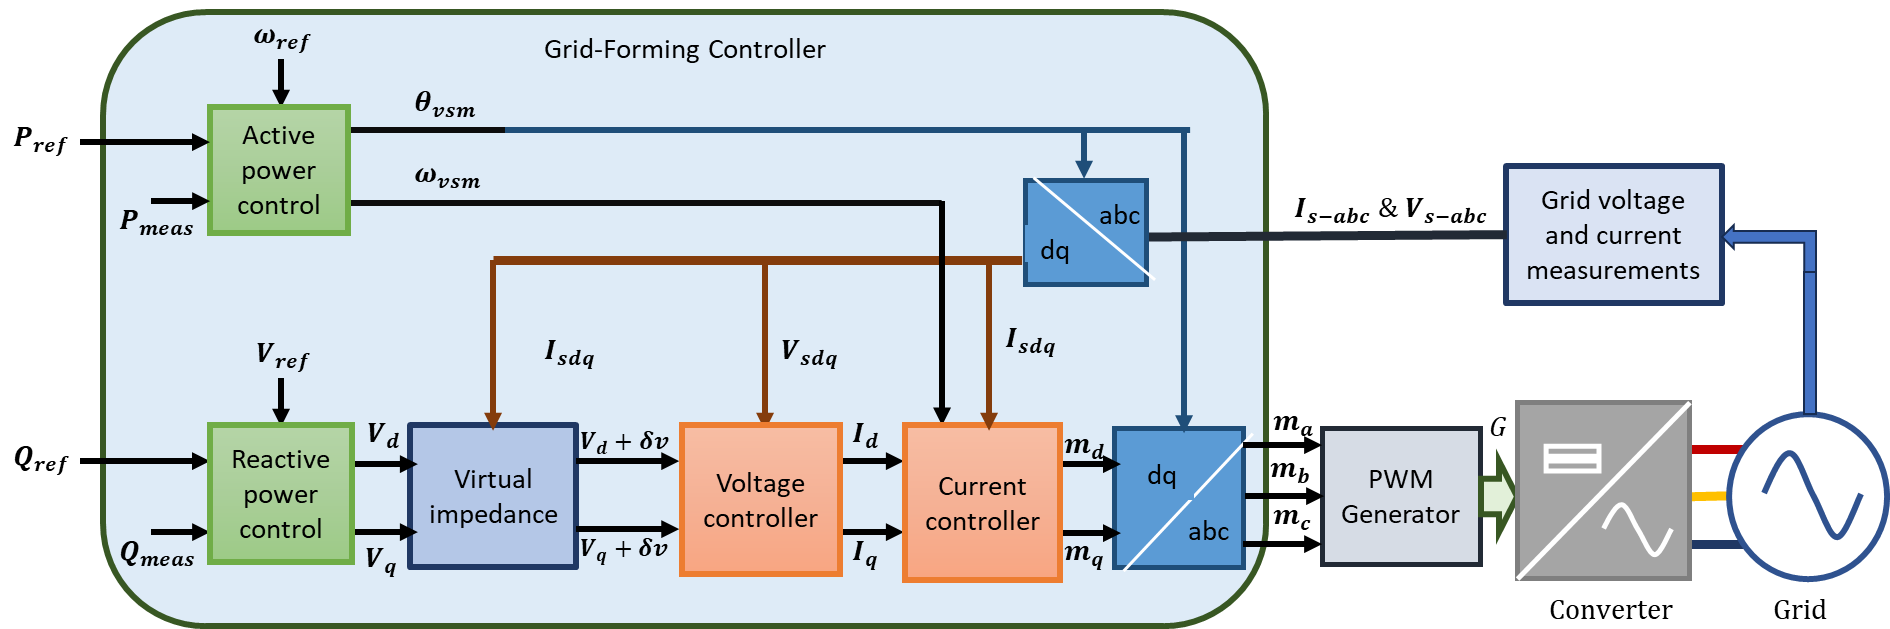

## Performance Requirements from Standards

### Grid-Forming Converter Standards

The operating standards of a grid-forming converter keep evolving. There are many standards that define an acceptable operation of a GFM converter. This workflow conforms to the grid-forming specification standards of the United States Federal Energy Regulatory Commission (FERC) and Great Britain: 

- GC0137 $-$ Minimum Specification Required for Provision of GB grid-forming (GBGF) Capability [1]

- FERC Order Nos. 827 $-$ Reactive Power Requirements for Non-Synchronous Generation [2].

- FERC Order Nos. 828 $-$ Requirements for Frequency and Voltage Ride Through Capability of Small Generating Facilities [3].

- FERC Order Nos. 842 $-$ Essential Reliability Services and the Evolving Bulk-Power System—Primary Frequency Response [4]

### Grid-Forming Converter Operating Region

In the GC01037 grid code standard, GFM converter plant must have predefined frequency response characteristics over the full range within the region defined by the green and blue lines in this figure [1]. Inside that envelope, the GFM converter operates in a stable mode without disconnecting from the network.       

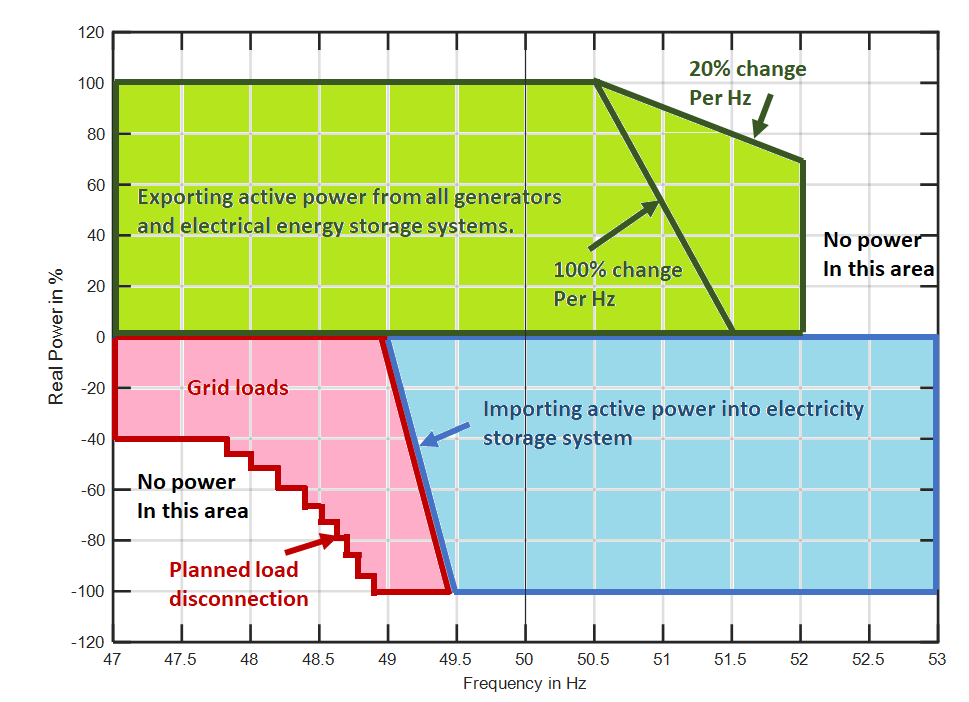 

### Ride-Through Requirements 

In the GC0137 [1], FERC. order nos. 827 [2], 828 [3], and 842 [4] standards, all inverter-based resources must have ride-through capability for voltage and frequency disturbances. Any unwanted GFM converter tripping, as a direct or indirect result of a voltage or frequency disturbance within a ride-through region, constitutes a non-compliance with standard practice. Current limiting methods and power controllers help the GFM converter to stay connected during permissible transient disturbances. The GC0137 grid code mandates the GFM converter plant to inject a reactive current of at least its rated peak current when the output voltage drops to zero.

This figure [1] shows the GFM converter reactive current requirement during low-voltage reactive current. The injected reactive current must be on or above a line drawn as shown in this figure.

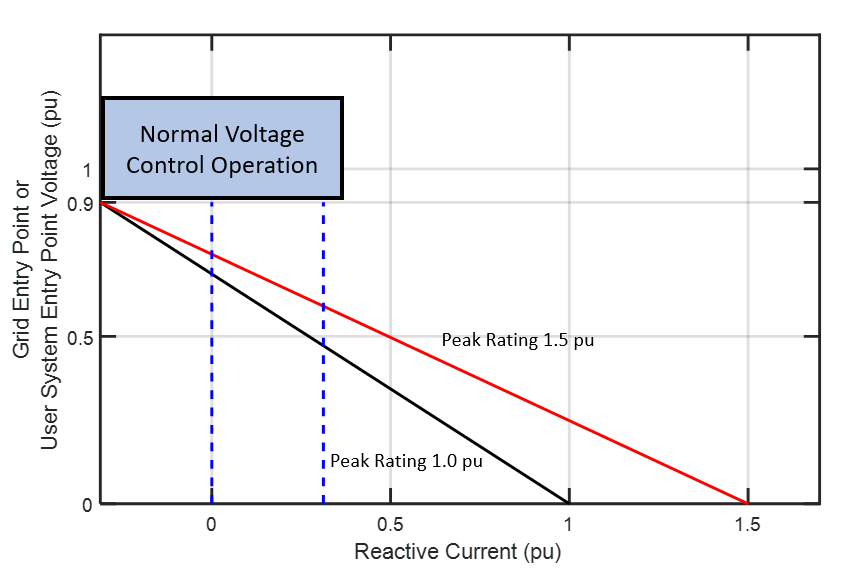

   This figure [1] shows the injection time response requirements of the GFM converter for a low-voltage fault current.

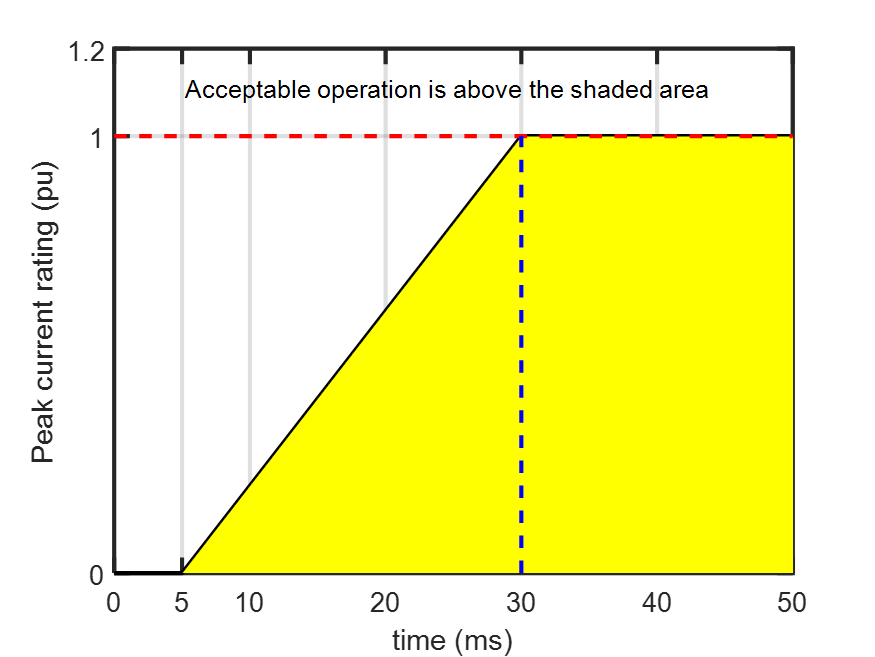

### Standard Grid-Forming Test

This design solution studies the performance of a grid-forming converter using test scenarios from the GC0137 [1] grid code standard. This figure shows a grid-forming converter test scenario from the GC0137 grid code standard. The standard requires stable operation during grid disturbances, including changes in system voltage, frequency, and phase.    

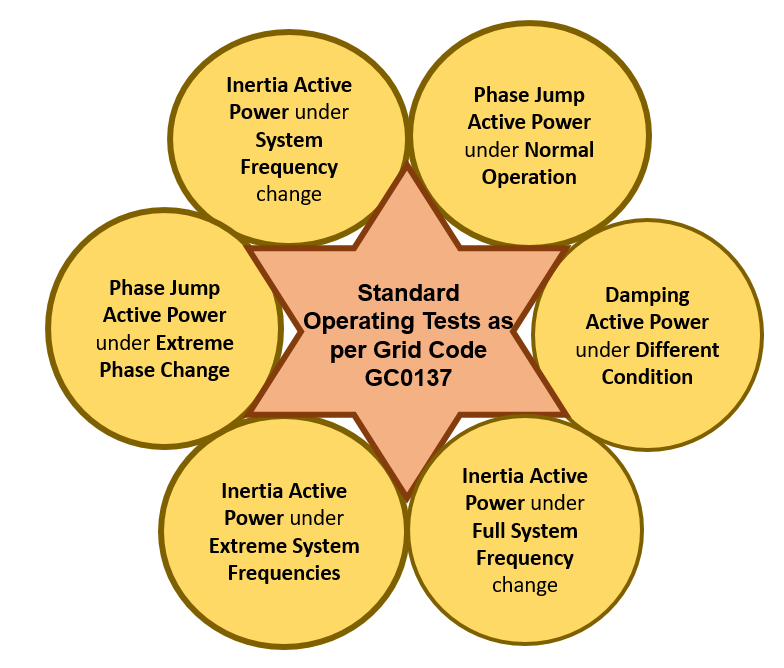

## Run Model and Plot Results

### Simulation Settings

To select between the different grid voltage, frequency, phase, local load, short-circuit ratio (SCR), X/R ratio, power reference, islanding mode, faults, and predefined test scenarios, set the appropriate test condition variables as time-table data.

The [`GridFormingConverterTestCondition`](matlab:open('./GridFormingConverterTestCondition.mlx')) MLX file creates nine test variables for the 13 predefined test scenarios. Use the `simulationTime` variable to set the total simulation time, in seconds. You can run the test scenarios either programmatically or through the model canvas using test scenario mask.

To study a particular test condition, you must configure the model with these inputs:

- Active power control method

- Fault ride-through method

- Grid parameters

- Test scenario

 
% Load the grid-forming converter test condition inputs                                                           
edit 'GridFormingConverterTestCondition';
GridFormingConverterTestCondition; % Input the test condition

#### **Select Active Power Controller**

To specify the active power control method, set the value of `testCondition.activePowerMethod` to either `Virtual Synchronous Machine or Droop Control.`

testCondition.activePowerMethod = 'Virtual Synchronous Machine'; 
% Select the active power control algorithm

The virtual synchronous machine control method mimics synchronous machine inertia and damping. The controller damping power is computed by using either a constant frequency reference or measured grid system frequency. 

To specify the damping power computation option, set the value of the` gridInverter.vsm.dampingPowerOption` variable to either `Grid Frequency Measurement or Constant Frequency Reference.`

The damping power based on the grid frequency measurement offers better performance during the grid frequency disturbances. 

#### **Select Fault Ride-Through Method**

To specify the fault ride-through option, set the value of the `gridInverter.vsm.currentLimitMethod` variable to either:

- `Virtual Impedance`

- `Current Limiting`

- `Virtual Impedance and Current Limiting`

% Select the fault ride-through algorithm
testCondition.currentLimitMethod = 'Virtual Impedance';  

#### **Select Grid Parameters**

 The performance of the GFM converter is influenced by the grid SCR and X/R ratios. 

#### Short-Circuit Ratio

This figure shows a GFM converter connected to the grid through a transformer, transmission line, and grid impedance. They influence the grid short-circuit ratio and X/R ratio. 

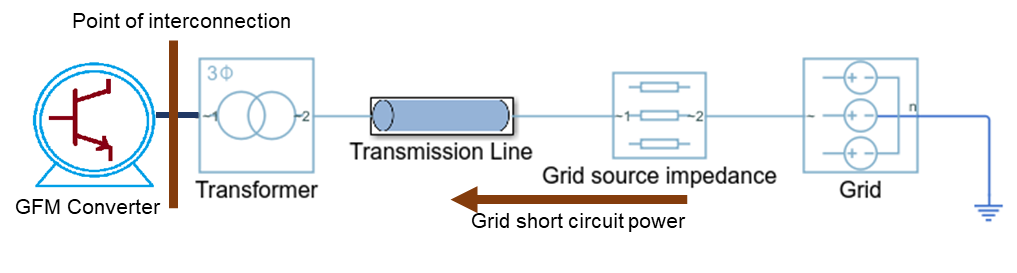

The short-circuit ratio is the ratio between the grid short-circuit power at the point of interconnection and the GFM converter rated power. 


$$\textrm{SCR}=\frac{\textrm{SCVAg}}{\textrm{VArated}}=\frac{1}{|\textrm{Zpu}|}$$


where:

- **SCVAg** $-$ Short-circuit power supplied by the grid for the fault at the point of interconnection. 

- **VArated** $-$ GFM converter rated power

- **Zpu **$-$ Per unit total impedance is a sum of the transformer, transmission line, and grid source impedances.

X/R ratio is the ratio between the reactance and the resistance of the total impedance connected between the GFM converter and the grid.

The values of the SCR and X/R ratio influence the performance of the GFM converter. A network with a low SCR value offers very high impedance from the GFM converter output to the grid. To keep this impedance to an acceptable range, in this design solution, a 500 kVA, 415V, 50 Hz GFM converter is connected to a network with an SCR value greater than one. However, a high-power GFM converter can operate in a network with SCR values less than one. You can use this generic GFM control implementation and test harness of this design solution for the high power grid-forming units that are connected to a network with SCR values less than one.

To set the grid SCR value, specify the value of the `testCondition.SCR` variable. To set the grid X/R ratio, specify the value of the `testCondition.XbyR` variable. In this design solution, specify the SCR values from 1 to 4 and the X/R ratio from 1 to 10.

  
 % Select the grid short-circuit ratio values from 1 to 4
 testCondition.SCR = 2.5;
 % Select the grid X/R ratio values from 1 to 10
 testCondition.XbyR = 5;

#### Select Test Scenario

This design solution provides a test harness to investigate a grid-forming converter for 13 predefined test scenarios. To choose between these test scenarios, use both the` testCondition.testCondition` variable and the nine test-condition variable profiles defined in the [`GridFormingConverterTestCondition`](matlab:open('./GridFormingConverterTestCondition.mlx')) MLX file.

The 13 test scenarios are classified into two test groups: 

- Grid-forming controller in normal and faulted operating conditions. 

- Grid-forming controller in standard grid code test conditions.

#### Grid-Forming Controller Under Normal and Faulted Operating Conditions

These tests ensure a stable GFM converter operation during changes in the active power reference, reactive power reference, grid voltage, local load, fault, and islanded operating conditions.

To choose the test scenario, set the values of the `testCondition.testCondition` variable to:

- `Normal operation `$-\;$Simulate the model without any disturbance.

- `Change in active power reference` $-\;$Instantaneous change in the active power reference.

- `Change in reactive power reference` $-\;$Instantaneous change in the reactive power reference.

- `Change in grid voltage` $-\;$Instantaneous change in the grid voltage.

- `Change in local load` $-\;$Instantaneous change in the local load.

- `Temporary three-phase fault` $-\;$Generate a three-phase-to-ground fault and clear it after a specific amount of time.

- `Islanding condition` $-$ During steady-state operation, the grid circuit breaker trips to simulate the GFM converter at the islanded condition.

#### Grid-Forming Controller Under Standard Grid Code Test Conditions [1]

These tests simulate some of the operating scenario specified in the GC0137 [1] grid code standard. As per grid code, these tests are conducted at the full active power and zero reactive power operating condition. 

To choose the test scenario, set the values of the `testCondition.testCondition` variable to:

- `Change in grid frequency 1Hz/s, +0.5Hz` $-$Increase the system frequency by 0.5 Hz at the rate of 1 Hz/s.

- `Change in grid frequency 2Hz/s, +2Hz `$-$ Increase the system frequency by 2 Hz at the rate of 2 Hz/s.

- `Change in grid frequency 2Hz/s, +2Hz and 1Hz/s till -5Hz` $-\;\;$Increase the system frequency by 2 Hz at the rate of 2 Hz/s, wait for 5 seconds, and then decrease the frequency by 5 Hz at the rate of 1 Hz/s.

- `Change in grid phase by 10 degrees` $-$ Apply an instantaneous change in the phase by 10 degrees.

- `Change in grid phase by 60 degrees` $-$ Apply an instantaneous change in the phase by 60 degrees.

-  `Permanent three-phase fault` $-$ Generate a three-phase-to-ground fault and measure the reactive power.

To open the test condition variable file

 
edit 'GridFormingConverterTestCondition';

### Simulation Result Plot Function

Use the [PlotGridFormingConverter](matlab:open('PlotGridFormingConverter')) MATLAB function to plot the 13 test scenario simulation results. This function also analyzes the measured active power and frequency to check if the system reached a stable state at the end of the simulation time.

The `PlotGridFormingConverter` MATLAB function take these inputs:

- `testCondition` $-$ Simulation settings, specified as a struct of five variables.

- `plotFlag` $-$ Option to plot the results and summary MATLAB table. To plot the results, set this input to 1.

- Optional third variable $-$ Set this to `"All"` to simulate all the test scenarios at once.

The function plots the system performance curves and provides the steady-state test result summary in table format.

## **Simulation Results**

The grid-forming converter is simulated in 13 test scenarios. The results are plotted and then summarized in a table. You can define the test scenario and the test variable profile with time in the test [`GridFormingConverterTestCondition`](matlab:open('./GridFormingConverterTestCondition.mlx')) MLX file. 

### Test Configuration

To setup the required test scenario, set the values for the `testCondition` variable. 

The `testCondition` variable defines:

- Active power method

- Current limiting method

- Grid short-circuit ratio

- Grid X/R ratio

- Test name

The below code, sets the active power control method of the grid-forming converter to "Virtual Synchronous Machine", the fault ride-through method to "Virtual Impedance" with a grid short-circuit ratio of 2.5 and a X/R ratio of 5.

 
% Configure the test scenario 
% Select the active power control method
testCondition.activePowerMethod = 'Virtual Synchronous Machine'; 
% Select the fault ride-through method
testCondition.currentLimitMethod = 'Virtual Impedance'; 
% Select the grid SCR value
testCondition.SCR = 2.5;
% Select the grid X/R ratio
testCondition.XbyR = 5;

### Normal Operation

This test condition simulates a grid-forming converter in normal operation without any disturbances.

 
% Select the operating scenarios
testCondition.testCondition = 'Normal operation'; 

Plot the simulation results. The plot title summarizes the test result and whether the system is stable.

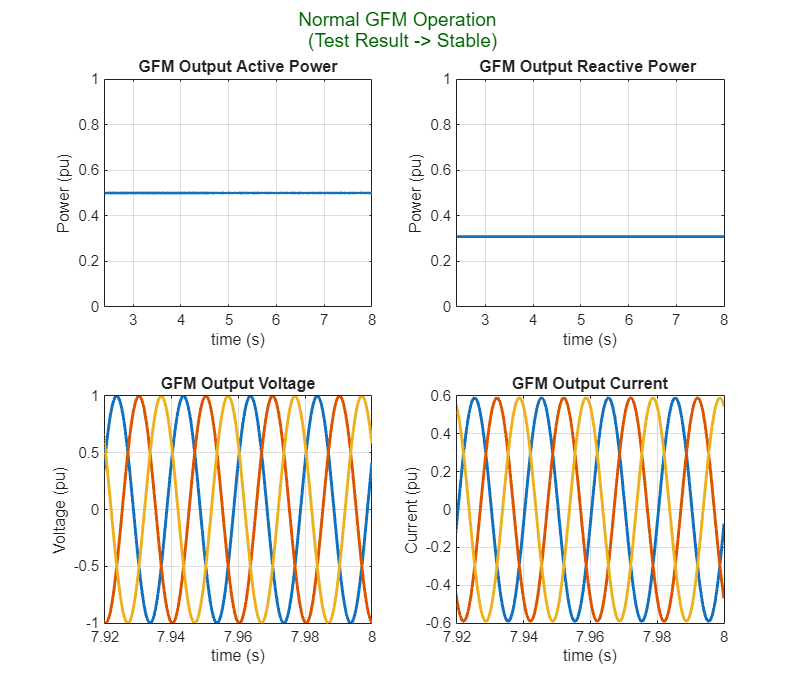

Steady State Grid-Forming Converter Output Measurement in pu
         TestName         ActivePower    ReactivePower    Voltage    Current    TestResult
    __________________    ___________    _____________    _______    _______    __________

    "Normal operation"        0.5           0.30815       0.99755    0.58877     "Stable" 



% Call the plot function with plotFlag = 1
outputTable = PlotGridFormingConverter(testCondition,1); %#ok<*NASGU> 

### Change in Input Reference

To analyze the performance of the grid-forming converter for specific control parameters, you can simulate the change in the active power reference, reactive power reference, local load, and grid system frequency.

#### Instantaneous **Change in Active Power Reference**

In this test scenario, the system experiences a instantaneous change in the active power reference. This test scenario allows you to study the GFM converter tracking ability, its response time, and output voltage fluctuations.

 
% Select the operating scenarios
testCondition.testCondition = 'Change in active power reference'; 

Simulate and plot the simulation results.

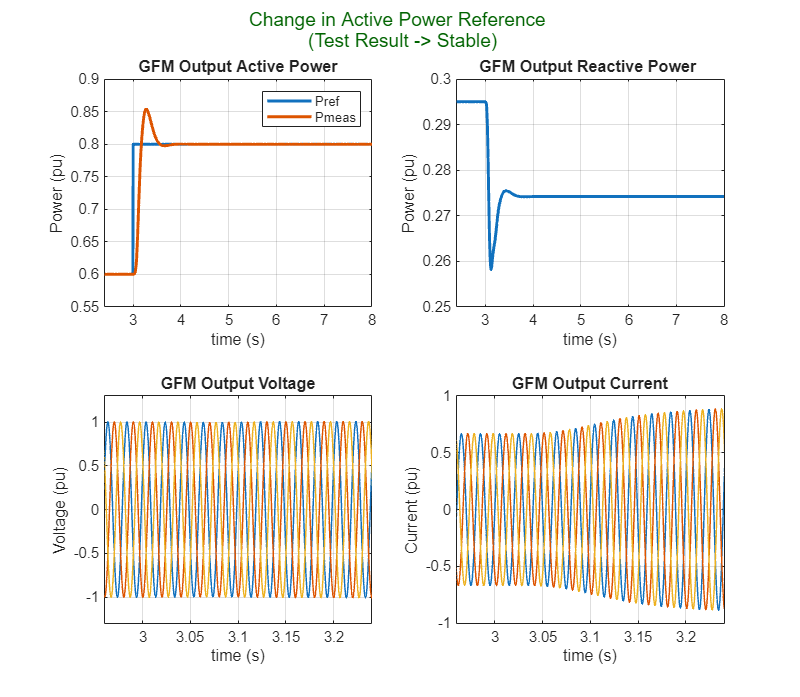

Steady State Grid-Forming Converter Output Measurement in pu
                 TestName                 ActivePower    ReactivePower    Voltage    Current    TestResult
    __________________________________    ___________    _____________    _______    _______    __________

    "Change in active power reference"        0.8           0.27422       1.0077     0.8392      "Stable" 



% Plot simulation outputs and provide test summary
outputTable = PlotGridFormingConverter(testCondition,1); 

### Test Summary for All Test Conditions

Set the `plotFlag` input of the PlotGridFormingConverter function to 0 and set 'All' to run the GFM converter in all 13 test scenarios. From the simulation test summary table, you can observe that, for all test scenarios, the GFM converter system is running in a stable condition.

Test summary table for all the test conditions

 
% Simulate all test scenarios to get test result summary, plotFlag set to zero
outputTable = PlotGridFormingConverter(testCondition,0, 'All'); 

Steady State Grid-Forming Converter Output Measurement in pu
                             TestName                             ActivePower    ReactivePower    TestResult
    __________________________________________________________    ___________    _____________    __________

    "Normal operation"                                                  0.5          0.30815       "Stable" 
    "Change in active power reference"                                  0.8          0.27422       "Stable" 
    "Change in reactive power reference"                                0.5          0.36069       "Stable" 
    "Change in grid voltage"                                            0.5          0.43535       "Stable" 
    "Change in local load"                                              0.5          0.15877       "Stable" 
    "Change in grid frequency 1Hz/s, +0

## Testing with Respect to Standard Grid Code

You can simulate some of the test scenarios from the grid code standard GC0137 [1]. The test scenarios include change in voltage, grid frequency, and phase. Stable grid-forming converter operation is observed as mandated in the grid code standard.

## Change in Full Grid System Frequency 

This test scenario increases the grid system frequency by 2 Hz at the rate of 2 Hz/s and then decrease it by 5 Hz at the rate of 1 Hz/s. The simulated results show that the grid-forming converter is operating in the stable region, supplying the required active and reactive power without disconnecting.

 
% Selecting the operating scenarios
testCondition.testCondition = ...
    'Change in grid frequency 2Hz/s, +2Hz and 1Hz/s till -5Hz'; 

Plot the simulation results.

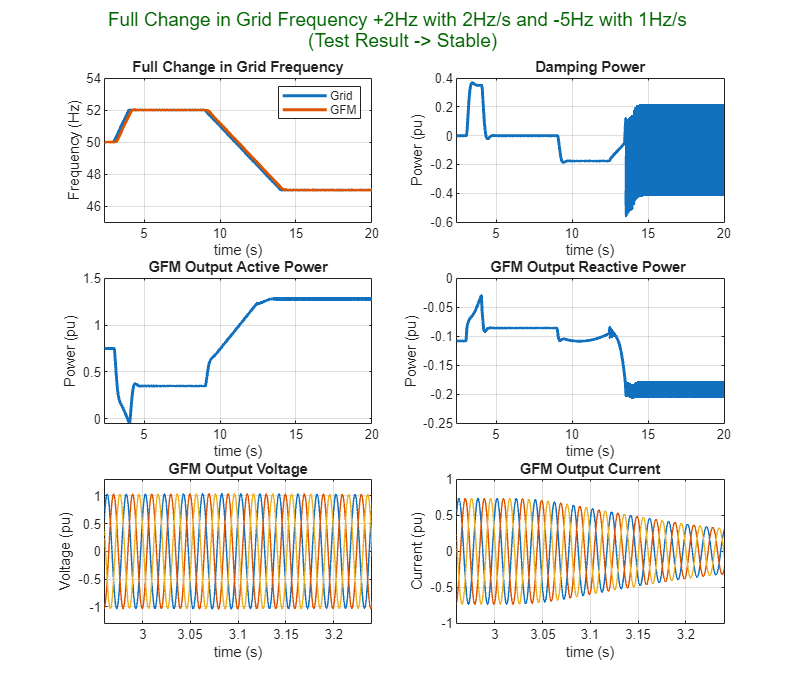

Steady State Grid-Forming Converter Output Measurement in pu
                             TestName                             ActivePower    ReactivePower    Voltage    Current    TestResult
    __________________________________________________________    ___________    _____________    _______    _______    __________

    "Change in grid frequency 2Hz/s, +2Hz and 1Hz/s till -5Hz"       1.275         -0.20108       0.87522    1.3334      "Stable" 



outputTable = PlotGridFormingConverter(testCondition,1);

### Instantaneous Change in Grid Phase Angle

This test scenario changes the grid phase by 60 degrees. The simulated results show that the grid-forming converter is operating in the stable region, supplying the required active and reactive power without disconnecting. 

 
% Selecting the operating scenarios
testCondition.testCondition = 'Change in grid phase by 60 degrees'; 

Plot the simulation results.

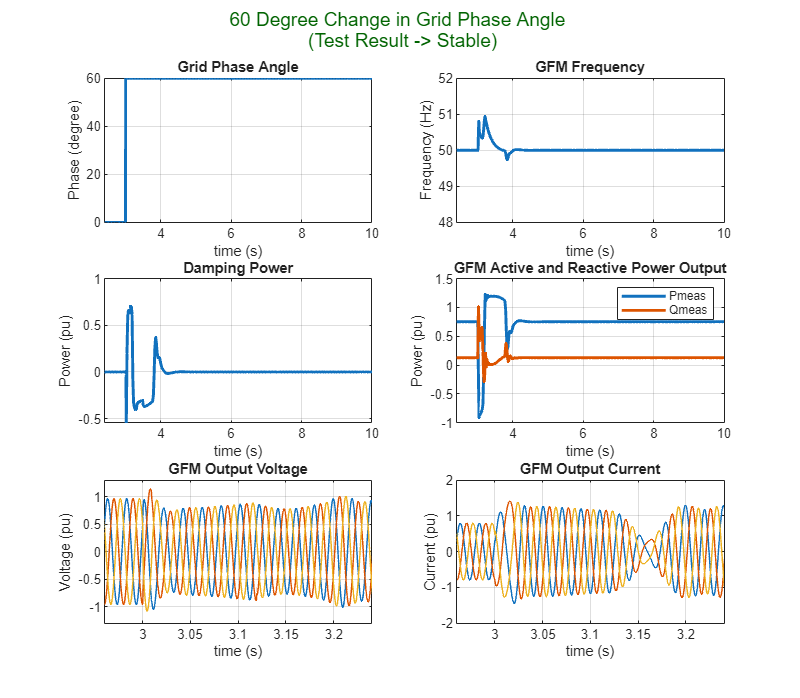

Steady State Grid-Forming Converter Output Measurement in pu
                  TestName                  ActivePower    ReactivePower    Voltage    Current    TestResult
    ____________________________________    ___________    _____________    _______    _______    __________

    "Change in grid phase by 60 degrees"       0.75           0.12873       0.96138    0.79153     "Stable" 



outputTable = PlotGridFormingConverter(testCondition,1);

### Fault Ride-Through Characteristics

In this test scenario, you can simulate a grid-forming converter in the three-phase-to-ground (LLL-G) fault condition with different fault impedances. The fault reactive current injection is compared with the minimum injection current in the grid code standard GC0137 [1]. 

Use the [`PlotFaultCurrentVoltageEffects`](matlab:open('./PlotFaultCurrentVoltageEffects.m')) MATLAB function to simulate and plot the output under faulted conditions. 

 
% Select the operating scenarios
testCondition.testCondition = 'Permanent three-phase fault'; 
% Fault impedance array
faultImpedanceArray = [0.05 0.1 0.25 0.4]; % Three phase fault impedance

Plot the simulation results.

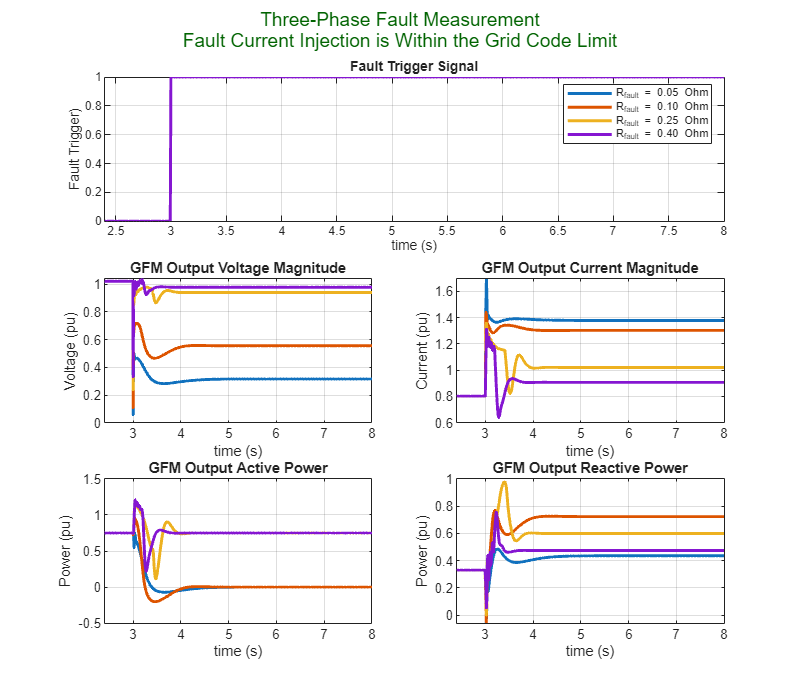

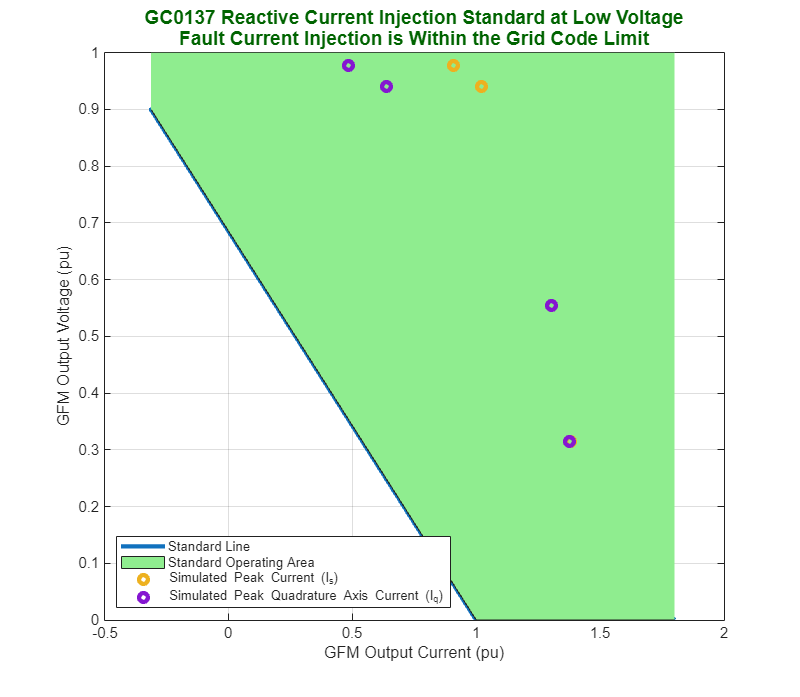

Steady State Grid-Forming Converter Output Measurement in pu
    FaultResistanceInOhm    ActivePower    ReactivePower    Voltage    MinimumStandardCurrent    MeasuredCurrentIs
    ____________________    ___________    _____________    _______    ______________________    _________________

            0.05            -2.3031e-08       0.43559       0.31545            0.54013                  1.379     
             0.1             1.3083e-09       0.72355       0.55486            0.19113                 1.3034     
            0.25                   0.75       0.59973       0.94008           -0.37045                 1.0215     
             0.4                   0.75       0.47461       0.97762           -0.42517                0.90787     



outValue = PlotFaultCurrentVoltageEffects(faultImpedanceArray, testCondition,1);

This figure plots the overall peak fault current (Is), and the peak quadrature axis fault current (Iq) for different fault impedances. This plot overlays the GC0137 [1] grid codes standard specification. The grid code mandates a minimum reactive power that a grid-forming converter must supply during the low voltage condition. From the plot and the test summary table, you can observe that for the above test condition a grid-forming converter is operating in the green shaded region as required in the GC0137 [1] grid code standard.

## Performance Studies of Grid-Forming Converter

To analyze the performance of a grid-forming converter, modify the control parameters and compare the results for different control methods. 

This design solution analyzes the performance of a grid-forming converter for different:

- VSM damping coefficient

- VSM inertia constant

- Fault ride-through methods

To plot the grid-forming converter performance, use the [`PlotDampingEffects`](matlab:open('PlotDampingEffects')), [`PlotInertiaConstantEffects`](matlab:open('PlotInertiaConstantEffects'))`,` and [P`lotCompareFaultRideThroughMethod`](matlab:open('PlotCompareFaultRideThroughMethod')) MATLAB functions. These functions also provide test summary tables.

### VSM Damping Coefficient Effects

This test studies the effect of the damping coefficient for different virtual synchronous machine damping coefficients. The damping coefficient helps the GFM converter to ride-through oscillations but slows down the GFM converter response. Use the [`PlotDampingEffects`](matlab:open('./plotDampingEffects.m')) MATLAB function to simulate and plot the test results for different grid-forming converter damping coefficients.

#### GFM Converter Response for Sudden Change in Active Power Reference

You can simulate the effects of damping ratio during an instantaneous change in the active power reference. The higher damping coefficient results in a slower GFM converter response.

 
% Select the operating scenarios
testCondition.testCondition = 'Change in active power reference';
dampingArray = [0.6 2 4];


Plot the simulation results.

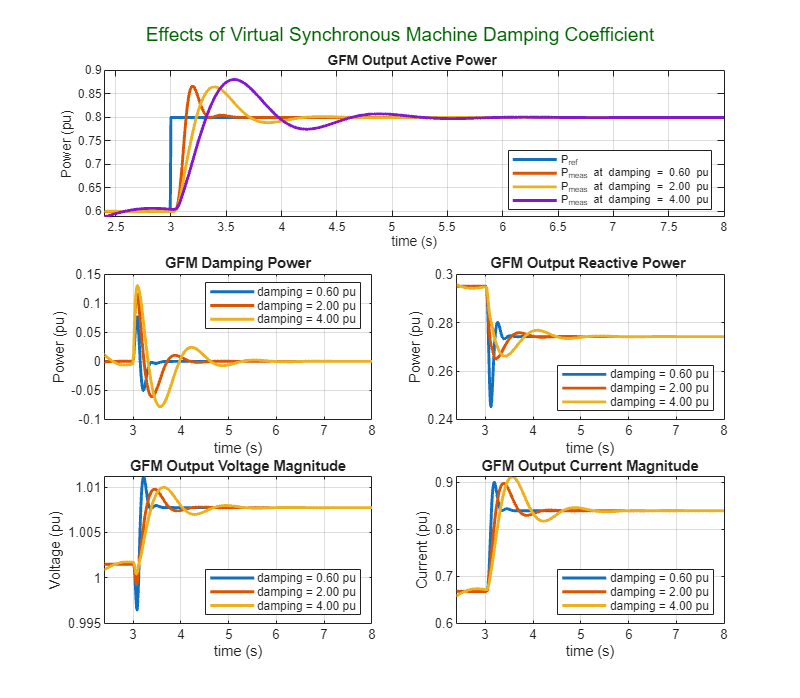

Steady State Grid-Forming Converter Output Measurement in pu
    Damping    ActivePower    ReactivePower    Voltage    Current    FrequencyHz
    _______    ___________    _____________    _______    _______    ___________

      0.6            0.8         0.27422       1.0077      0.8392        50     
        2            0.8         0.27422       1.0077      0.8392        50     
        4        0.79999         0.27422       1.0077     0.83919        50     



outValue = PlotDampingEffects(dampingArray, testCondition,1);

### VSM Inertia Constant Effects

#### GFM Converter Response for Sudden Change in Active Power Reference

You can simulate the effects of different inertia constants for an instantaneous change in the active power reference. A higher inertia constant leads to an oscillatory GFM converter response. Use the [`PlotInertiaConstantEffect`](matlab:open('./PlotInertiaConstantEffects.m')) MATLAB function to simulate and plot the test results for different grid-forming converter inertia coefficients.

 
% Select the operating scenarios
testCondition.testCondition = 'Change in active power reference';
% Inertia constant, pu
inertiaConstantArray = [0.1 0.4 1 3]; 

Plot the simulation results.

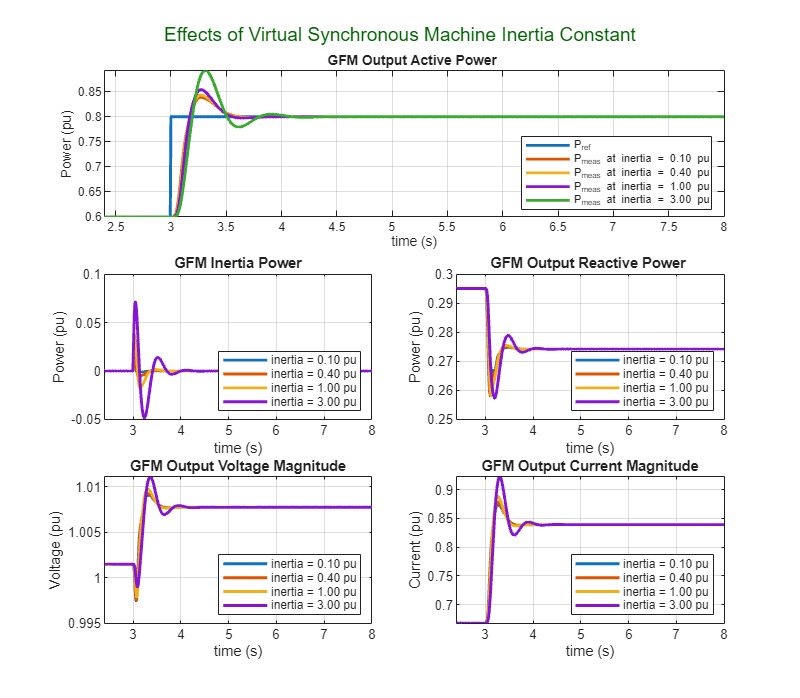

Steady State Grid-Forming Converter Output Measurement in pu
    Inertia    ActivePower    ReactivePower    Voltage    Current    FrequencyHz
    _______    ___________    _____________    _______    _______    ___________

      0.1          0.8           0.27422       1.0077     0.8392         50     
      0.4          0.8           0.27422       1.0077     0.8392         50     
        1          0.8           0.27422       1.0077     0.8392         50     
        3          0.8           0.27422       1.0077     0.8392         50     



outValue = PlotInertiaConstantEffects(inertiaConstantArray, testCondition,1);

### Comparing Fault Ride-Through Methods

This test condition examines the fault ride-through of the GFM converter with three current limiting control methods: 

- Virtual impedance

- Current limiting

- Virtual Impedance and current limiting

 Use the [`PlotCompareFaultRideThroughMethod`](matlab:open('./PlotCompareFaultRideThroughMethod.m')) MATLAB function to simulate and plot the test results for three fault ride-through methods.

 
% Select the operating scenario
testCondition.testCondition = 'Permanent three-phase fault';

Plot the simulation results.

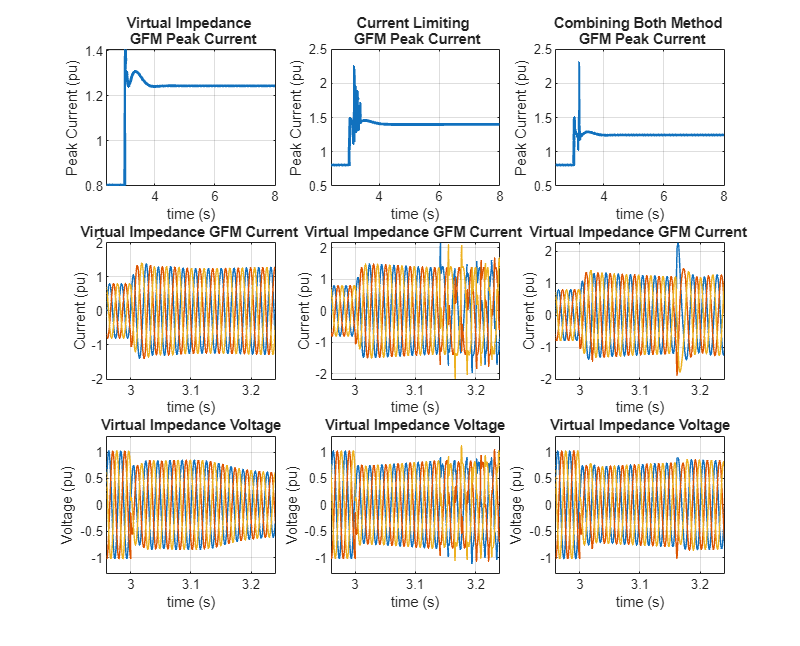

Steady State Grid-Forming Converter Output to Compare Fault Ride-Through Methods
                    TestName                    ActivePower    ReactivePower    Voltage    Current    TestResult
    ________________________________________    ___________    _____________    _______    _______    __________

    "Virtual Impedance"                            1.13e-10       0.88021       0.70764    1.2438      "Stable" 
    "Current Limiting"                          -4.1968e-05        1.0047       0.53412       1.4      "Stable" 
    "Virtual Impedance and Current Limiting"     1.1916e-10       0.88021       0.70764    1.2438      "Stable" 



outTable = PlotCompareFaultRideThroughMethod(testCondition, 1);

## Conclusion

Use this grid-forming converter model for different ratings and applications by providing the controller and other specification parameters. This design solution implements the generic grid-forming converter and analyzes its performance under various test scenarios. The test results are compared to the grid code standards to ensure desirable operation and compliance.

## References

[1].[GC0137: the Minimum Specification Required for Provision of GB grid-forming (GBGF) Capability (formerly Virtual Synchronous Machine/VSM Capability)](https://www.nationalgrideso.com/industry-information/codes/grid-code-old/modifications/gc0137-minimum-specification-required).

[2]. [Federal Energy Regulatory Commission FERC Order Nos. 827, Reactive Power Requirements for Non-Synchronous Generation](https://www.nerc.com/FilingsOrders/us/Pages/2016FERCOrdersRules.aspx).

[3]. [Federal Energy Regulatory Commission FERC Order Nos. 828,Requirements for Frequency and Voltage Ride Through Capability of Small Generating Facilities.](https://www.nerc.com/FilingsOrders/us/Pages/2016FERCOrdersRules.aspx)

[4]. [Federal Energy Regulatory Commission FERC Order Nos. 842, Essential Reliability Services and the Evolving Bulk-Power System—Primary Frequency Response.](https://www.nerc.com/FilingsOrders/us/Pages/2016FERCOrdersRules.aspx)

Copyright 2023 The MathWorks, Inc.